# Introduction to Code Generation with Simulink

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2025_11_05_CodeGenerationIntro/CodeGeneration.prj)

One of the key benefit of Simulink is that you can generate C/C++ code from the model, using [Simulink Coder](https://www.mathworks.com/products/simulink-coder.html) and [Embedded Coder](https://www.mathworks.com/products/embedded-coder.html).

If you are not familiar with the code generated from Simulink, looking at it for the first time can be intimidating. In this post, I will try to demystify that a little bit.

## The Simulation Loop

In order to understand the code generated from Simulink, you first need to understand how Simulink solves the equations implemented as blocks in the model. 

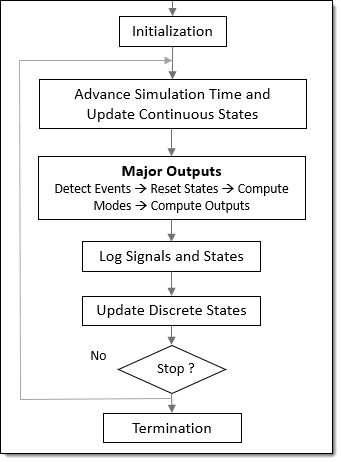

Obviously, this diagram is a simplification of what Simulink actually does. To get the full picture, I recommend this page: [Simulink Engine Interaction with C S-Functions - MATLAB & Simulink](https://www.mathworks.com/help/simulink/sfg/how-the-simulink-engine-interacts-with-c-s-functions.html).

For models without continuous states (which is the case for the majority of production code generation user interested to look at the generated code), the equations for all blocks are solved in two groups:

- **Major Output:** Simulink computes the output of all blocks as a function function of their current inputs and states


$$\left\lbrack y\left(k\right)\right\rbrack =f\left(\left\lbrack u\left(k\right)\right\rbrack ,\left\lbrack x\left(k\right)\right\rbrack \right)$$


- **Update Discrete States:** Simulink computes the value of the states for the next step, as a function of the block inputs and current states.


$$\left\lbrack x\left(k+1\right)\right\rbrack =f\left(\left\lbrack u\left(k\right)\right\rbrack ,\left\lbrack x\left(k\right)\right\rbrack \right)$$


Now, let's look at a specific example.

## Example: Discrete State-Space

In my opinion, the best classic example to illustrate the basics of how Simulink works is a Discrete State-Space system ([State-space representation - Wikipedia](https://en.wikipedia.org/wiki/State-space_representation)). It results in one equation for the Output phase and one equation for the Update phase.

While Simulink includes a [Discrete State-Space block](https://www.mathworks.com/help/releases/R2025b/simulink/slref/discretestatespace.html), for the purpose of this blog post, I decided to implement it as typically seen in controls or dynamic systems books:

mdl = "testCG";
open_system(mdl)

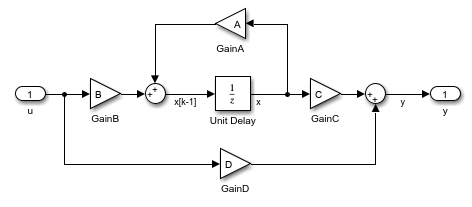

In terms of equations, this gives two equations, mapping to the above diagram:

- Major Output:


$$y\left(k\right)=\textrm{Cx}\left(k\right)+\textrm{Du}\left(k\right)$$


- Update Discrete States:


$$x\left(k+1\right)=\textrm{Ax}\left(k\right)+\textrm{Cu}\left(k\right)$$


## The Generated Code

If you generate code for the above model, you will see a folder like this being generated:

slbuild("testCG");

### Searching for referenced models in model 'testCG'.
### Total of 1 models to build.
### Starting build procedure for: testCG
### Successful completion of build procedure for: testCG

Build Summary

Top model targets:

Model   Build Reason                   Status                        Build Duration
testCG  Incremental checksum changed.  Code generated and compiled.  0h 0m 35.91s  

1 of 1 models built (0 models already up to date)
Build duration: 0h 0m 38.893s


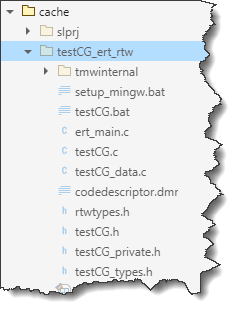

with the default settings (minus the comments), Simulink Coder produces this step function (`testCG.c`). As you can see, it contains code for the two equations described above.

For typical production code generation use cases, most users prefer combining `Output` and `Update`, so Simulink Coder combines them into a single `Step` function. The are options to control this behavior if needed.

### Data Structures

To understand this code, let's look at how the data is organized. In most code generated from Simulink, you will find 4 data structures:

- **Inputs ("U"):** a structure with one field *per Inport*

- **Outputs ("Y"):** a structure with one field *per Outport*

- **Parameters ("P"):** a structure with one field *per parameter*

- **States ("DW"): **a structure with one field *per stat*e. (**DW** stands for **D**iscrete **W**ork vector)

Knowing that, we can find their declaration in the generated header file (`testCG.h`):

The values for block parameters are specified in the data file (`testCG_data.c`),:

For the initial state, the value is set in the initialize function (`testCG.c`)

To observe the relationship between the blocks in the model and the generated code, I recommend opening the [Code Panel](https://www.mathworks.com/help/ecoder/ug/trace-simulink-model-objects-in-generated-code.html). The highlighting works both ways. You can hover over parts the code and the corresponding blocks gets highlighted. You can also click on blocks in the canvas and the corresponding code gets highlighted:

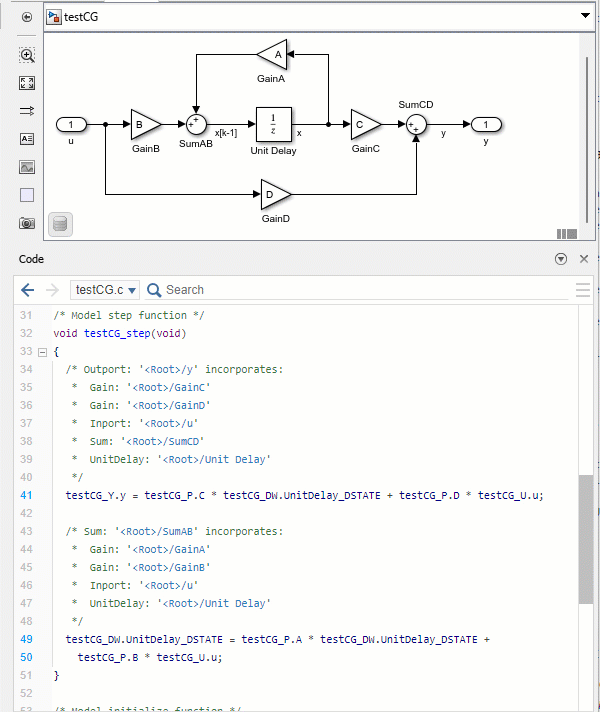

### A little bit more about block parameters

While inputs, outputs, and states map to individual modeling elements, parameters can be used in multiple blocks and this is reflected in the generated code. Let's take this simple example where I use a variable "`b`" in both the Bias and Gain block:

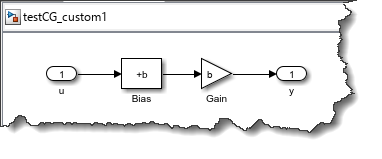

 The comments in the data file (`testCG_custom1_data.c`) indicates that the same C code variable is used by two blocks:

In the equation for the step function, we can confirm that the same variable "`testCG_custom1_P.b`" is used for both the bias and the gain:

## Optimizations

At this point, you might be wondering:

*You said that Simulink computes the output and states of each block. The model has 10 blocks and I only see two equations, what happened?*

The answer is simple: By default, Simulink Coder optimizes the generated code!

Simulink has tons of optimization settings that I will not cover in details here. Personally, the most frequent reason I have to disable optimizations is debugging, to inspect intermediary variables more easily. 

This can easily be set in the model configuration:

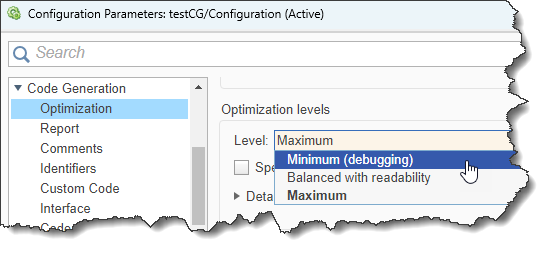

Programmatically, this can be done using:

set_param("testCG","OptimizationLevel","level0");

And we now get one line of code per block:

As you can see, this introduces a new data structure **("B"**), containing the output of the individual blocks.

Don't forget to switch back the optimization level to maximum when you're done debugging!

set_param("testCG","OptimizationLevel","level2");

## Customization

In many cases, you don't need and don't want to customize the generated code. In fact, if you generate code for Rapid Prototyping or Hardware-In-the-Loop simulation, you probably don't even want to look at the generated code!

However, in some cases, you might have a good reason for wanting to customize the generated code. Good news, with [Embedded Coder](https://www.mathworks.com/products/embedded-coder.html), it is possible to customize almost everything in the generated code.

One common and simple use case is the need to interface with hand-written code. For that, you want to tell Simulink Coder that a specific modeling element should become a specific variable in the generated code. Let's look at two examples of that.

### Customization 1: Exporting a State

Let's say that we want the generated code to read and write the state of the Unit Delay block in our state-spate system to a variable named "`x`" that the hand-written code will be able to access. 

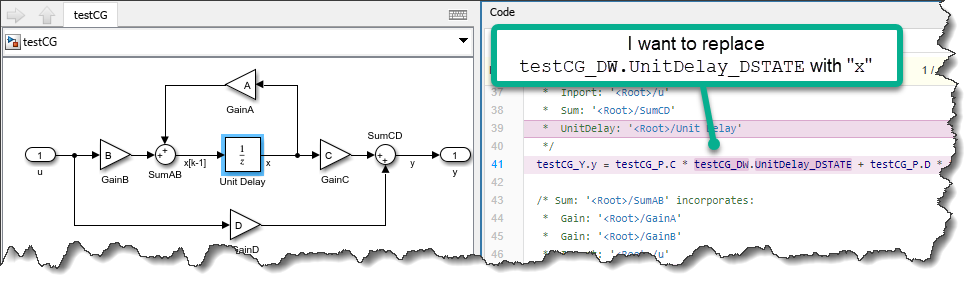

### Customization 2: Exporting a Signal

As discussed in [this previous post](https://blogs.mathworks.com/simulink/2025/03/10/using-test-points-to-log-signals-for-software-in-the-loop-simulation), another common customization is to retain a specific signal in the generated code. For our example, let's say we want to be able to access "`A*x`" and "`B*u`":

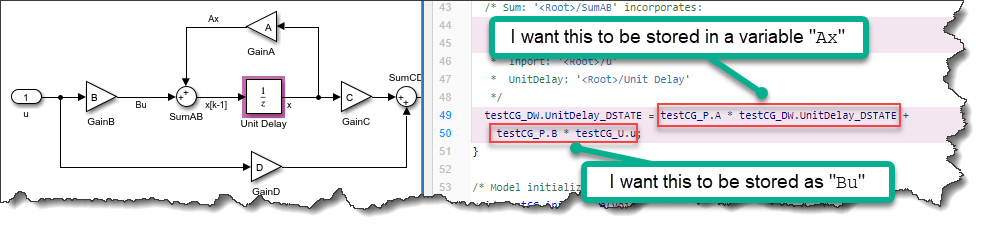

To implement those two customization, you can use the [Code Mapping Editor](https://www.mathworks.com/help/rtw/ref/codemappingseditorc.html). Go to the Signals/States tab, and change the [Storage Class](https://www.mathworks.com/help/ecoder/ug/choose-a-built-in-storage-class-for-controlling-data-representation-in-the-generated-code.html) of the state of the Unit Delay block and of the two signals `Ax` and `Bu` to `ExportedGlobal`. In the Property Inspector, you can specify the Identifier you want to appear in the generated code:

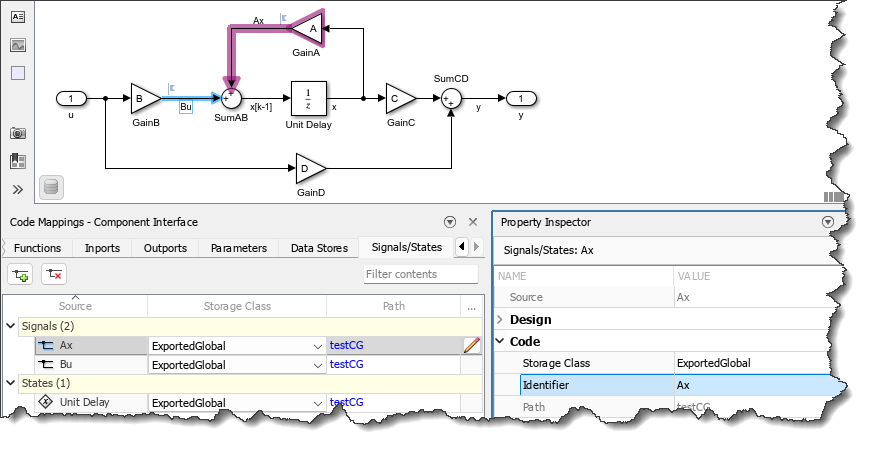

With that change, the generated code becomes:

When generating code for the simple examples I publish on this blog, I like to abuse this capability a little bit. With a few more clicks in the Code Mapping Editor, I can turn the generated code into this:

You probably don't want to go that extreme for the code generated for your application!

## Now it's your turn

I think it's enough for an intro to the code generated from Simulink. Let us know in the comments below if there are other code generation related topics you would like to see covered on this blog.